# 绘制24种碳源模拟实验

1.读取模型

%{
adapterLocation = fullfile(findGECKOroot, ...
    'eciML1515', 'eciML1515Adapter.m'); 
ModelAdapterManager.setDefault(adapterLocation);
cd('D:\learning software\matlab\GECKO-3.2.1\eciML1515\models')
ecModel = loadEcModel('ecModel.yml');
model = importModel(fullfile(findGECKOroot, ...
    'eciML1515', 'models', 'iML1515.xml'));
cd('D:\learning software\matlab\GECKO-3.2.1\eciML1515')


2.数据准备

filename = '拟合数据校准ecmodel.xlsx'; 
sheet1 = '葡萄糖有氧';
sheet2 = '葡萄糖无氧';
sheet3 = '24种碳源生长速率';
sheet4 = '实验值';
data1 = readtable(filename, 'Sheet', sheet1);
data2 = readtable(filename, 'Sheet', sheet2);
data3 = readtable(filename, 'Sheet', sheet3);
data4 = readtable(filename, 'Sheet', sheet4);
data = {};
num_groups = length(data4{:, 1});
for i = 1:num_groups
    if i == 1
        reaction_ids = data1{:, 1};
        lower_bounds = data1{:, 2};
        upper_bounds = data1{:, 3};
    elseif i == 2
        reaction_ids = data2{:, 1};
        lower_bounds = data2{:, 2};
        upper_bounds = data2{:, 3};
    else
        reaction_ids = data3{:, 1}(i-2);
        lower_bounds = data3{:, 2}(i-2);
        upper_bounds = data3{:, 3}(i-2);
    end
    new_data_group.reaction_ids = reaction_ids;
    new_data_group.lower_bounds = lower_bounds;
    new_data_group.upper_bounds = upper_bounds;
    new_data_group.experimental_values = data4{:, 1}(i);

    data{i} = new_data_group;
end
%}
% ecModel = best_ecModel;
data_for_plot = data;
model = importModel(fullfile(findGECKOroot, ...
    'eciML1515', 'models', 'iML1515.xml'));

	2doxg6p[c]
	3amp[p]
	3cmp[p]
	2dglc[p]
	3cmp[e]
	3ump[e]
	2dglc[e]
	3amp[e]
	3ump[p]
	2dglc[c]



3.计算酶约束模型和普通模型的预测值

enzyme_predict = zeros(length(data_for_plot), 1);      % 作为预测值，作为x
normal_predict = zeros(length(data_for_plot), 1);      % 作为预测值，作为x
lb_for_normal = zeros(length(data_for_plot), 1);
experimental_value = zeros(length(data_for_plot), 1);  % 作为实验值，作为y
carbon_source = cell(length(data_for_plot), 1);        % 作为点名称

copy_ecModel = ecModel;

for i = 1:length(data_for_plot)
% for i = 1:2
    % 应用反应约束
    reaction_ids = data_for_plot{i}.reaction_ids;
    lower_bounds = data_for_plot{i}.lower_bounds;
    upper_bounds = data_for_plot{i}.upper_bounds;
    experimental_value(i) = data_for_plot{i}.experimental_values;
    ecModel = setParam(ecModel, 'lb', 'EX_glc__D_e', 0);
    for j = 1:length(reaction_ids)
        ecModel = setParam(ecModel, 'lb', reaction_ids{j}, lower_bounds(j));
        ecModel = setParam(ecModel, 'ub', reaction_ids{j}, upper_bounds(j));
    end
    
    % 求解预测值
    sol = solveLP(ecModel);
    enzyme_predict(i) = sol.f;
    if i > 2
        index = find(strcmp(ecModel.rxns, reaction_ids{1}));
        lb_for_normal(i) = sol.x(index);
        carbon_source(i) = data_for_plot{i}.reaction_ids;
    elseif i == 1
        index = find(strcmp(ecModel.rxns, 'EX_glc__D_e'));
        lb_for_normal(i) = sol.x(index);
        carbon_source{i} = 'EX_glc__D_e';
    elseif i == 2
        index = find(strcmp(ecModel.rxns, 'EX_glc__D_e'));
        lb_for_normal(i) = sol.x(index);
        carbon_source{i} = 'EX_glc__D_e';
    end
    ecModel = copy_ecModel;
end

copy_model = model;

for i = 1:length(data_for_plot)

    model = setParam(model, 'lb', 'EX_glc__D_e', 0);

    if i <= 2
        reaction_ids = data_for_plot{i}.reaction_ids;
        lower_bounds = data_for_plot{i}.lower_bounds;
        upper_bounds = data_for_plot{i}.upper_bounds;

        for j = 1:length(reaction_ids)
            model = setParam(model, 'lb', reaction_ids{j}, lower_bounds(j));
            model = setParam(model, 'ub', reaction_ids{j}, upper_bounds(j));
        end
        model = setParam(model, 'lb', carbon_source{i}, lb_for_normal(i));
    else
        model = setParam(model, 'lb', carbon_source{i}, lb_for_normal(i));
    end
    % 求解预测值
    sol_normal = solveLP(model);

    if isempty(sol_normal.f)
        normal_predict(i) = 0;
    else
        normal_predict(i) = sol_normal.f;
    end
    model = copy_model;
end

% 计算 MSE
mse_enzyme = mean((enzyme_predict - experimental_value).^2);
mse_normal = mean((normal_predict - experimental_value).^2);

% 输出结果
fprintf('MSE for enzyme_predict: %.4f\n', mse_enzyme);

MSE for enzyme_predict: 0.0153


fprintf('MSE for normal_predict: %.4f\n', mse_normal);

MSE for normal_predict: 2.3311


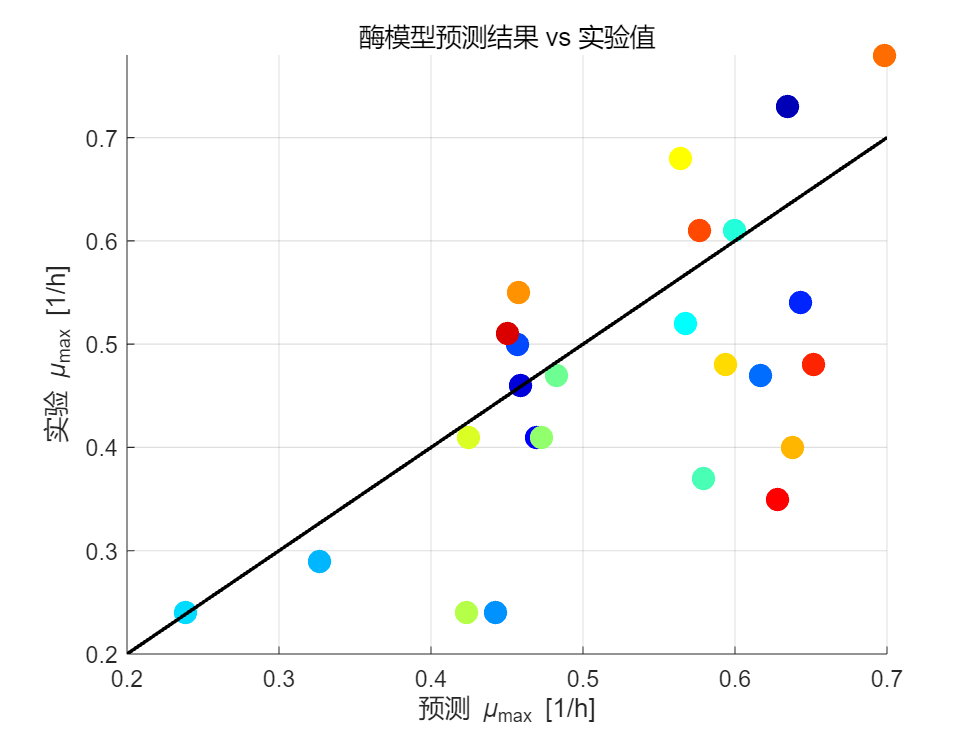


% 创建颜色映射（根据不同的碳源赋予不同颜色）
color_map = jet(length(carbon_source));  
marker_sizes = 100;  

% 绘制酶模型预测 vs 实验值
figure;
hold on;
for i = 1:length(carbon_source)
    scatter(enzyme_predict(i), experimental_value(i), marker_sizes, color_map(i, :), 'filled');
end
plot(xlim, xlim, 'k', 'LineWidth', 1.5); % 替换成 y=x 线
xlabel('预测 \mu_{max} [1/h]');
ylabel('实验 \mu_{max} [1/h]');
title('酶模型预测结果 vs 实验值');
grid on;
axis tight;
hold off;

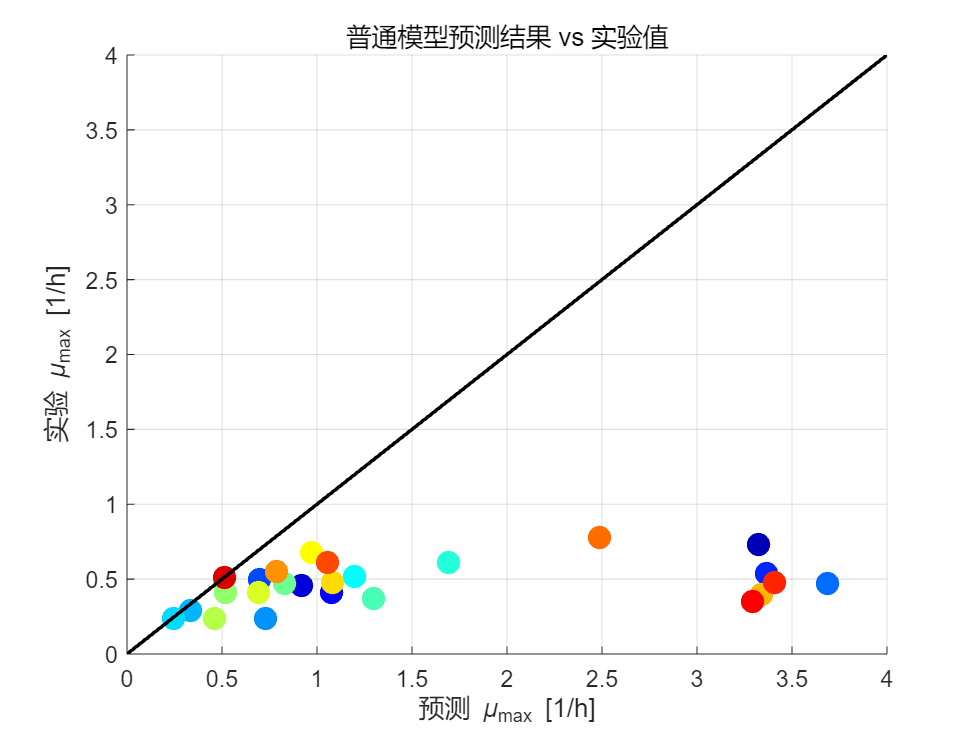


% 绘制普通模型预测 vs 实验值（交换x和y轴）
figure;
hold on;
for i = 1:length(carbon_source)
    scatter(normal_predict(i), experimental_value(i), marker_sizes, color_map(i, :), 'filled');
end
plot(xlim, xlim, 'k', 'LineWidth', 1.5);   % 绘制回归直线
xlabel('预测 \mu_{max} [1/h]');
ylabel('实验 \mu_{max} [1/h]');
title('普通模型预测结果 vs 实验值');
grid on;
axis tight;
hold off;

% 创建图形(学习率历史)
figure;
plot(0:(length(learning_rate_history)-1), learning_rate_history, '-o', 'LineWidth', 2);

函数或变量 'learning_rate_history' 无法识别。

xlabel('Iteration');
ylabel('Learning Rate');
title('Learning Rate History');
grid on;